# Debug

## Find matches in the 3 images and show them

clear;
load('SFM_results/B_1_2_10_KAZE');
disp(size(tracks,2));

   393



% find multi view points
mask=zeros(size(tracks));

for i=1:size(tracks,2)
    if size(tracks(i).ViewIds,2)>2
        mask(i)=1;
    end
end
mask=logical(mask);
disp(sum(mask));

   161



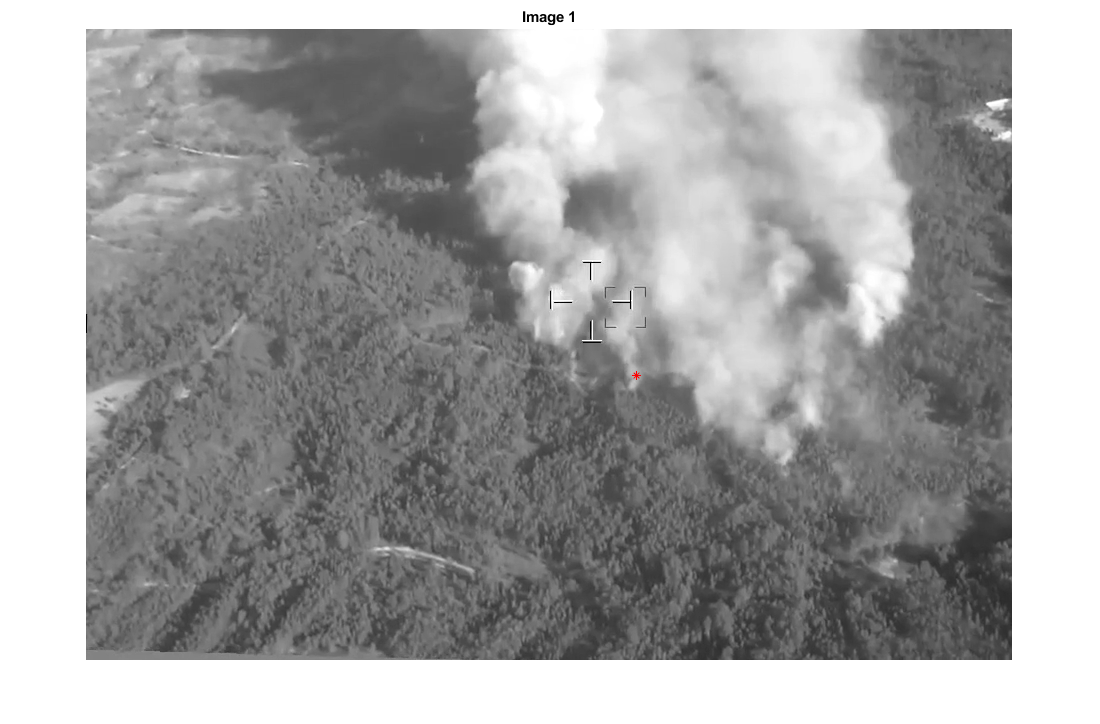

% select frames
f1=1;f2=2;f3=3;
% collect features from those 3 frames
t=tracks(mask);
p1=zeros(size(t,2),2);
p2=zeros(size(t,2),2);
p3=zeros(size(t,2),2);
for i=1:size(tracks(mask),2)
    if t(i).ViewIds(1)==f1 && t(i).ViewIds(2)==f2 && t(i).ViewIds(3)==f3
        %disp(t(i).ViewIds);
        p1(i,:)=t(i).Points(1,:);
        p2(i,:)=t(i).Points(2,:);
        p3(i,:)=t(i).Points(3,:);
        %disp(t(i).Points);
    end
end
mask= p1(:,1)~=0;
p1=p1(mask,:); p2=p2(mask,:); p3=p3(mask,:);

% show the 3 images and the features for each
i=1;
figure; imshow(images{f1});hold on;scatter(p1(i,1),p1(i,2),'r*'); title("Image 1");

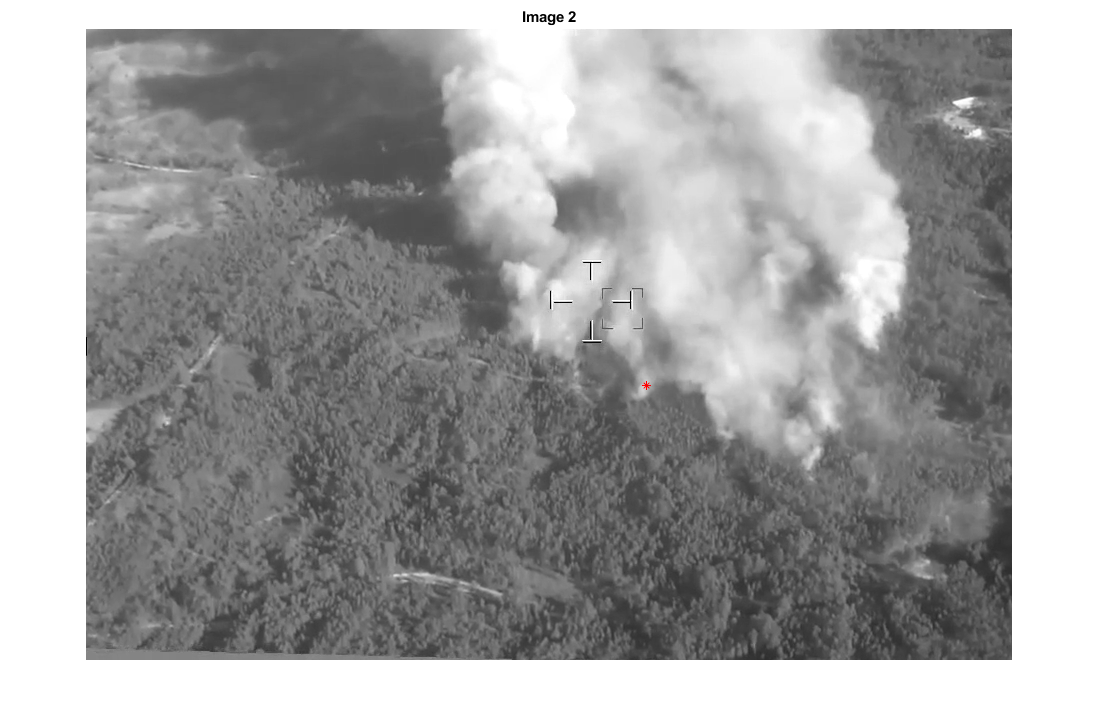

figure; imshow(images{f2});hold on;scatter(p2(i,1),p2(i,2),'r*');title("Image 2");

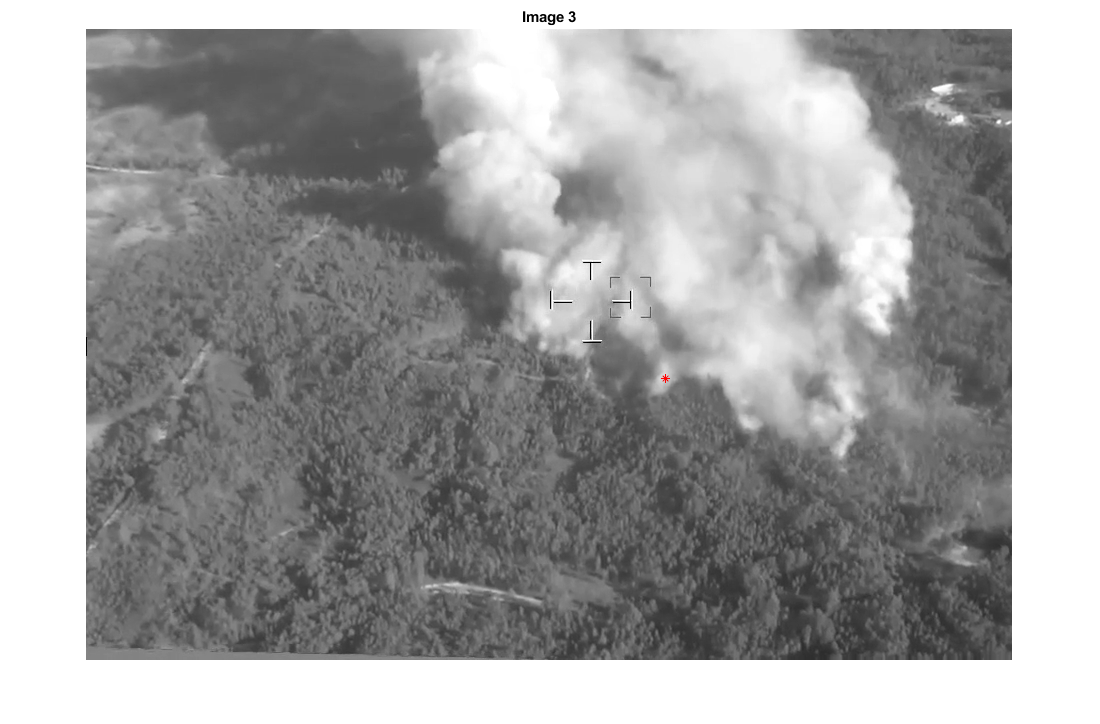

figure; imshow(images{f3});hold on;scatter(p3(i,1),p3(i,2),'r*');title("Image 3");

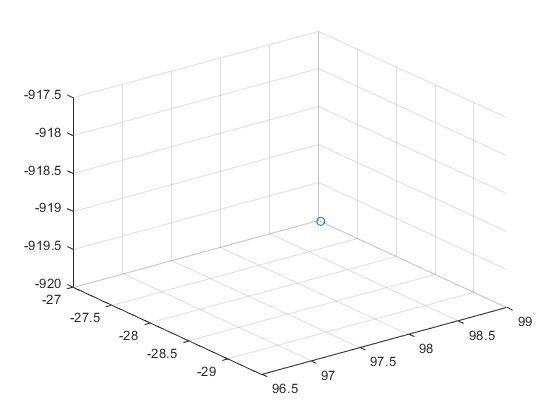

%% Triangulate the position of these points
% t -> tracks of the views f1 f2 f3
% c -> camPoses of the views
points=triangulateMultiview(t,camPoses,intrinsics);

% plot points
points= points(abs(points(:,3))<2000,:);
figure;
scatter3(points(i,1),points(i,2),points(i,3));

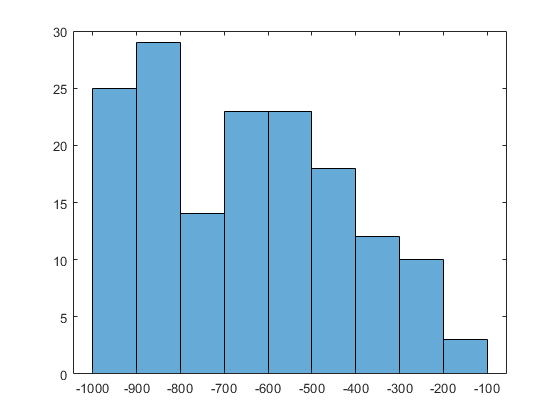

figure; histogram(points(:,3));

## Stereo results

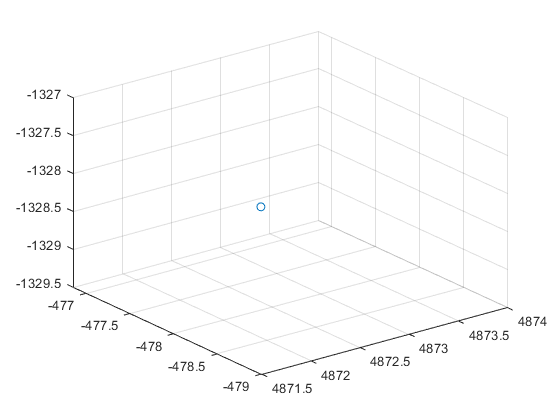

camMatrix1 = cameraMatrix(intrinsics, ... 
    angle2dcm( yaw(1), pitch(1), roll(1),'ZYZ'), cam_pos(1,:));
camMatrix2 = cameraMatrix(intrinsics, ... 
    angle2dcm( yaw(2), pitch(2), roll(2),'ZYZ'), cam_pos(2,:));

points3D = triangulate(p1(i,:), p2(i,:), camMatrix1, camMatrix2);
scatter3(points3D(:,1),points3D(:,2),points3D(:,3));